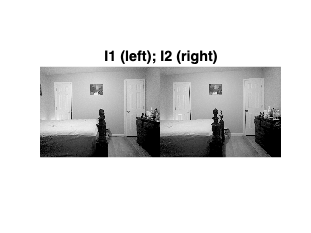

I1 = imread("./images/image_left.png");
I2 = imread("./images/image_right.png");

% Convert to grayscale.
I1gray = im2gray(I1);
I2gray = im2gray(I2);


% Display both images side by side.
figure
imshowpair(I1,I2,"montage")
title("I1 (left); I2 (right)")

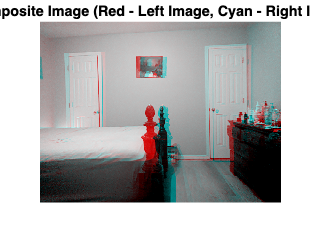


% color composite demonstrating the pixel-wise differences between the images
figure 
imshow(stereoAnaglyph(I1,I2))
title("Composite Image (Red - Left Image, Cyan - Right Image)")

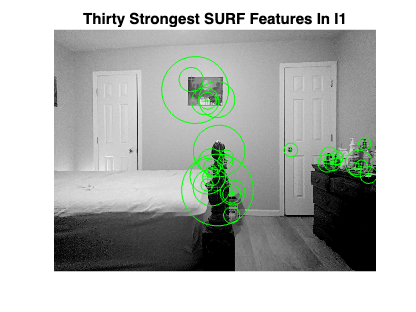



% Collect Interest Points from Each Image
blobs1 = detectSURFFeatures(I1gray,MetricThreshold=2000);
blobs2 = detectSURFFeatures(I2gray,MetricThreshold=2000);


% Visualize the location and scale of the thirty strongest SURF features in I1 and I2.
figure 
imshow(I1)
hold on
plot(selectStrongest(blobs1,30))
title("Thirty Strongest SURF Features In I1")

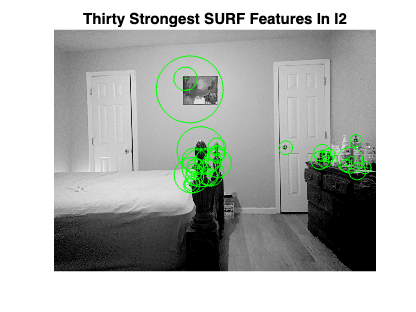


figure
imshow(I2)
hold on
plot(selectStrongest(blobs2,30))
title("Thirty Strongest SURF Features In I2")

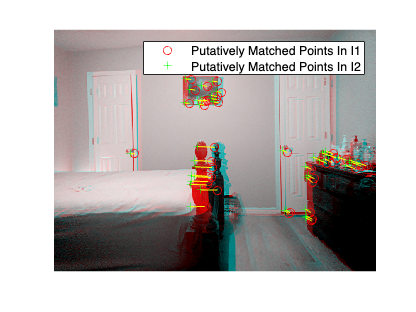



% Find Putative Point Correspondences
[features1,validBlobs1] = extractFeatures(I1gray,blobs1);
[features2,validBlobs2] = extractFeatures(I2gray,blobs2);

% Use the sum of absolute differences (SAD) metric to determine indices of matching features.
indexPairs = matchFeatures(features1,features2,Metric="SAD", ...
MatchThreshold=5);

% Retrieve locations of matched points for each image
matchedPoints1 = validBlobs1(indexPairs(:,1),:);
matchedPoints2 = validBlobs2(indexPairs(:,2),:);

% Show matching points on top of the composite image, which combines stereo images.
figure 
showMatchedFeatures(I1, I2, matchedPoints1, matchedPoints2)
legend("Putatively Matched Points In I1","Putatively Matched Points In I2")

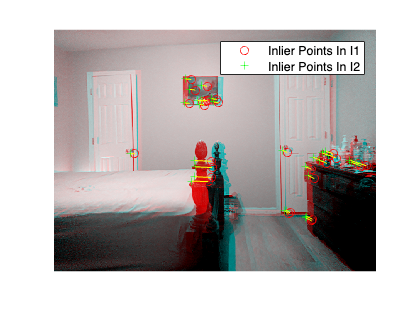



% Remove Outliers Using Epipolar Constraint
[fMatrix, epipolarInliers, status] = estimateFundamentalMatrix(...
  matchedPoints1,matchedPoints2,Method="RANSAC", ...
  NumTrials=10000,DistanceThreshold=0.1,Confidence=99.99);
  
if status ~= 0
    error('Failed to estimate the fundamental matrix. Check the quality and quantity of matched points.');
elseif isEpipoleInImage(fMatrix, size(I1))
    error('The epipole is inside the left image. Check camera alignment or consider using image rectification.');
elseif isEpipoleInImage(fMatrix', size(I2))
    error('The epipole is inside the right image. Check camera alignment or consider using image rectification.');
end


inlierPoints1 = matchedPoints1(epipolarInliers, :);
inlierPoints2 = matchedPoints2(epipolarInliers, :);

figure
showMatchedFeatures(I1, I2, inlierPoints1, inlierPoints2)
legend("Inlier Points In I1","Inlier Points In I2")

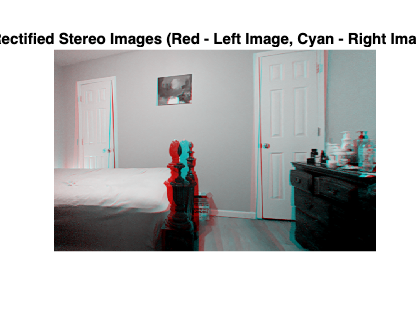


% Rectify Images
[tform1, tform2] = estimateStereoRectification(fMatrix, ...
  inlierPoints1.Location,inlierPoints2.Location,size(I2));

% Rectify the stereo images, and display them as a stereo anaglyph
[I1Rect, I2Rect] = rectifyStereoImages(I1,I2,tform1,tform2);
figure
imshow(stereoAnaglyph(I1Rect,I2Rect))
title("Rectified Stereo Images (Red - Left Image, Cyan - Right Image)")